**Google Project Sunroof **

Potential Solar Energy Generation by the region for all identified potential roof spaces and buildings

Importing the Metadata

data = readtable("sunroof_solar_potential_by_censustract.csv");

% Observation Variables
solar_kW_median_total = sortrows(table2array(data(:,5:6)),2);

kW_median = table2array(data(:,5));
kW_total = table2array(data(:,6));

sunlight_total = table2array(data(:,30));
carbon_offset = table2array(data(:,1));

% Feature Inputs

% Latitude Inputs
lat_avg = table2array(data(:,7));
lat_min = table2array(data(:,9));
lat_max = table2array(data(:,8));

% Longitude Inputs
lng_avg = table2array(data(:,10));
lng_min = table2array(data(:,12));
lng_max = table2array(data(:,11));

% Setting Data Matrices for each Observation and Feature Input Analysis
kW_median_lat_avg = sortrows([kW_median lat_avg], 2);
kW_median_lng_avg = sortrows([kW_median lng_avg], 2);
kW_total_lat_avg = sortrows([kW_total lat_avg], 2);
kW_total_lng_avg = sortrows([kW_total lng_avg], 2);

Visualizing the Data

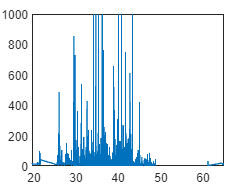

xyz = sortrows([kW_total lat_avg lng_avg], 2);

plot(kW_median_lat_avg(:,2),kW_median_lat_avg(:,1))

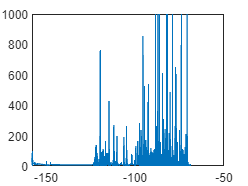

plot(kW_median_lng_avg(:,2),kW_median_lng_avg(:,1))

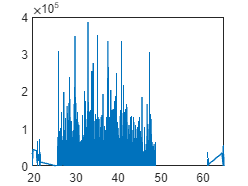


plot(kW_total_lat_avg(:,2),kW_total_lat_avg(:,1))

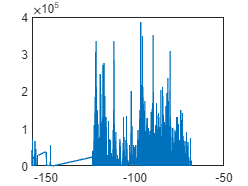

plot(kW_total_lng_avg(:,2),kW_total_lng_avg(:,1))

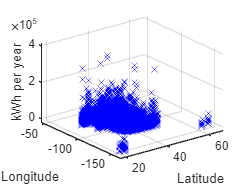


plot3(xyz(:,2),xyz(:,3),xyz(:,1),'x', 'Color','blue')
zlabel("kWh per year"); xlabel("Latitude"); ylabel("Longitude");
grid on

xlim([17.3 67.3])
ylim([-164 -45])
zlim([-20000 420000])

**Power Generation due to total Solar Intensity detected in the Region**

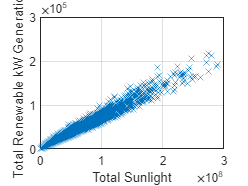

% First Erasing Null and Introduce Average Values to fill in the blank

% Average Values
sun_avg = sum(sunlight_total,'omitnan')/(size(sunlight_total,1)-sum(isnan(sunlight_total)));
kW_avg = sum(kW_total,'omitnan')/(size(kW_total,1)-sum(isnan(kW_total)));

% Erasing Null 
sunlight_total = fillmissing(sunlight_total,"constant",sun_avg);
kW_total = fillmissing(kW_total,"constant",kW_avg);

plot(sunlight_total, kW_total, 'x')
xlabel("Total Sunlight")
ylabel("Total Renewable kW Generation")
xlim([0 3e8])
grid on

Linear Regression Model y = a*x + b

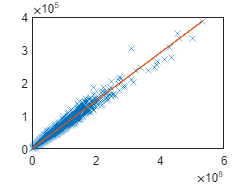

x = sunlight_total;
y = kW_total;

p = polyfit(x,y,1); % [a b] for ax+b in first-order
ypred = polyval(p,x);

plot(x,y,'x'); hold on;
plot(x,ypred); hold off;

rmse = sqrt(mean((ypred-y).^2))

rmse = 2.6267e+03

rrmse = rmse/mean(y)

rrmse = 0.1534

Polynomial Regression

p = polyfit(x,y,2); % [a b] for ax+b in first-order

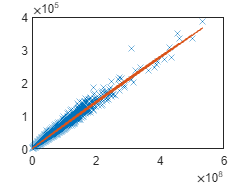

ypred = polyval(p,x);

plot(x,y,'x'); hold on;
plot(x,ypred); hold off;

rmse = sqrt(mean((ypred-y).^2))

rmse = 2.6118e+03

rrmse = rmse/mean(y)

rrmse = 0.1526

Feature Normalization

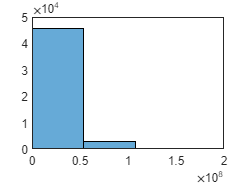

histogram(x,10)
xlim([0 2e8])

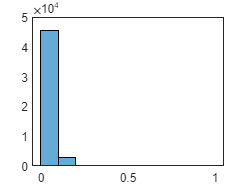


xnorm = (x - min(x))/(max(x)-min(x));
histogram(xnorm, 10);

Polynomial Regression with normalized feature

p = polyfit(xnorm,y,2);
ypred = polyval(p,xnorm);
plot(x,y,'x'); hold on;
plot(x,ypred); hold off;

rmse = sqrt(mean((ypred-y).^2))

rmse = 2.6118e+03

rrmse = rmse/mean(y)

rrmse = 0.1526

Effect of advancing to higher order of polynomial

maxdegree = 20;
for i = 1:maxdegree
    p = polyfit(xnorm,y,i);
    ypred = polyval(p,xnorm);
    error(i) = sqrt(mean((ypred-y).^2));
end

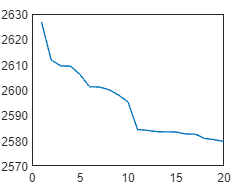


plot(1:maxdegree, error)

Split the dataset into training and validation sets

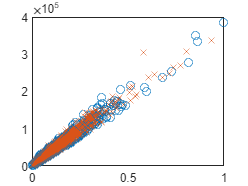

P = 0.5;
m = length(xnorm);
idx = randperm(m);
xtrain = xnorm(idx(1:round(P*m)));
xvalid = xnorm(idx(round(P*m)+1:end));
ytrain = y(idx(1:round(P*m)));
yvalid = y(idx(round(P*m)+1:end));

plot(xtrain,ytrain,'o'); hold on;
plot(xvalid,yvalid, 'x'); hold off;

Retrain a quadratic model with training/validation split

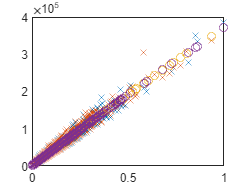

p = polyfit(xtrain,ytrain,2);
ypredtrain = polyval(p,xtrain);
ypredvalid = polyval(p,xvalid);

plot(xtrain,ytrain,'x'); hold on;
plot(xvalid,yvalid, 'x'); 
plot(xvalid,ypredvalid,'o');
plot(xtrain,ypredtrain, 'o'); hold off;

Effect of advancing to higher order (for training/validation sets)

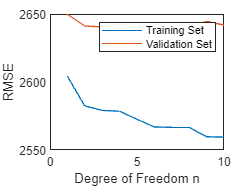

P = 0.50;
maxdegree = 10;

idx = randperm(m);
xtrain = xnorm(idx(1:round(P*m)));
xvalid = xnorm(idx(round(P*m)+1:end));
ytrain = y(idx(1:round(P*m)));
yvalid = y(idx(round(P*m)+1:end));

for i = 1:maxdegree
    p = polyfit(xtrain, ytrain, i);
    ypredtrain = polyval(p,xtrain);
    ypredvalid = polyval(p,xvalid);
    errortrain(i) = sqrt(mean((ypredtrain - ytrain).^2));
    errorval(i) = sqrt(mean((ypredvalid - yvalid).^2));
end

plot(1:maxdegree, errortrain, 1:maxdegree, errorval);
legend("Training Set", "Validation Set")
ylabel("RMSE")
xlabel("Degree of Freedom n")

Iterations on different training/test splits

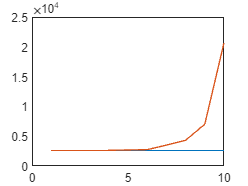

P = 0.50;
maxdegree = 10;
nrepeats = 100;
errortrain = zeros(maxdegree,1);
errorval = zeros(maxdegree,1);

for k = 1:nrepeats
    % random training/validation split
    idx = randperm(m);
    xtrain = xnorm(idx(1:round(P*m)));
    xvalid = xnorm(idx(round(P*m)+1:end));
    ytrain = y(idx(1:round(P*m)));
    yvalid = y(idx(round(P*m)+1:end));

    % loop on polynomial degrees
    for i = 1:maxdegree
        p = polyfit(xtrain, ytrain, i);
        ypredtrain = polyval(p,xtrain);
        ypredvalid = polyval(p,xvalid);
        errortrain(i) = errortrain(i) + sqrt(mean((ypredtrain - ytrain).^2));
        errorval(i) = errorval(i) + sqrt(mean((ypredvalid - yvalid).^2));
    end

end

errortrain = errortrain/nrepeats;
errorval = errorval/nrepeats;

plot(1:maxdegree, errortrain); hold on;
plot(1:maxdegree, errorval); hold off;


% Optimal Polynomial degree
[M,Order] = min(errorval)

M = 2.6172e+03

Order = 2

Predictions

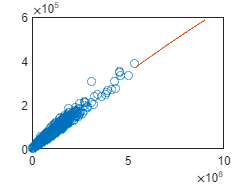

p = polyfit(xnorm,y,2);
xfuture = (5.4e8:37000:9e8);
xfuturenorm = (xfuture - min(x))/(max(x)-min(x));
yfuture = polyval(p,xfuturenorm);

plot(x,y,'o'); hold on;
plot(xfuture, yfuture); hold off; 

Miscellaneous

datapoints = length(x) + length(xfuture)

datapoints = 58452


Measured_Sunlight = x;
Increase_Sunlight = xfuture';

Measured_Generation = y;
Predicted_Generation = yfuture';

Writing to Excel

%%Original_data = table(Measured_Sunlight, Measured_Generation);
%%Predicted_data = table(Increase_Sunlight, Predicted_Generation);
%%writetable([Original_data Predicted_data],'sungenMLmodels.csv');

xlswrite('sungenMLmodels.xlsx', {'Measured Solar Intensity','Measured Generation','Predicted Solar Intensity','Predicted_Generation'}, 'Sheet1','A1')
xlswrite('sungenMLmodels.xlsx', Measured_Sunlight, 'Sheet1','A2')
xlswrite('sungenMLmodels.xlsx', Measured_Generation, 'Sheet1','B2')
xlswrite('sungenMLmodels.xlsx', Increase_Sunlight, 'Sheet1','C2')
xlswrite('sungenMLmodels.xlsx', Predicted_Generation, 'Sheet1','D2')


